# **Tutorials: Nonparametric Stitch Estimator (NSE) and Related Code**

This LiveScript tutorial with demonstrate how to generate random univariant samples for probability density functions (PDF) available to the Distributions class, as well as, how to simply use the Non-parametric Adaptive Partitioning (NAP) density estimator to find PDF estimates for those samples.

## Useful Links:

- The following directories are not explicitly required, yet are the defualt locations of relevant code or files on the main github repository: [Non-parametric Adaptive Partitioning (NAP) Density Estimation](https://github.com/zmerino/NSE)

- The NAP estimator leverages C++ code developed by Jenny Farmer and Donald Jacobs: [Non-parametric Maximum Entropy Density Estimation ](https://www.mathworks.com/matlabcentral/fileexchange/74834-multivariate-probability-density-estimation?s_tid=prof_contriblnk)- Affiliation with or Priniciple Investiagtor of the BioMolecular Physics Group (BMPG) at the University or North Carolina at Charlotte. 

- The most up to date C++ code can be found at the following github repository: [Jenny Farmer's c++ Github Repository](https://github.com/jennyfarmer/PDFAnalyze)

## Add Necessary Directories to the Workspace:

This directory contains all of the neccessary functions and classes to use the NAP estimator.

addpath("functions/")

This directory contains the C++ code for the estimator and by defualt will have the required MEX file compiled here. 

% addpath("cpp_code/")
addpath("cpp_code_smooth/")

## Compile C++ Code Into MEX File:

Make sure that the MinGW compiler has been installed on Windows or that g++ has been installed on linux/unix.

Execute the following command in Matlab inside of the cpp_code directory:

% run cpp_code/CompilePDF.m

## Distribution Class:

The class distributions allows a user to generate random samples for a various PDF distributions.

% Class assignment
actual = distributions;

Now let's generate a random sample

sample = load('xinning_data/f_sa0.05_sb0.005_real.txt');
sample = load('xinning_data/f_sa0.05_sb0.002_real.txt');

sample = 1 - sample

sample =     0.0005
    0.0035
    0.0021
    0.0003
    0.0037
    0.0040
    0.0050
    0.0093
    0.0163
    0.0053


## Nonparametric Stitch Estimator (NSE)

% nap object instantiation
nap = NAP;

% Generate the estimate object which contains relevant information
serial = true;
nap = nap.stitch(sample, serial);


% Extract relevant parameters from object after stich() method
fail_code = nap.failed;
x_nap = nap.sx;
pdf_nap = nap.sPDF;
cdf_nap = nap.sCDF;
u_nap = nap.u;
sqr_nap = nap.sqr;

Now plot the results

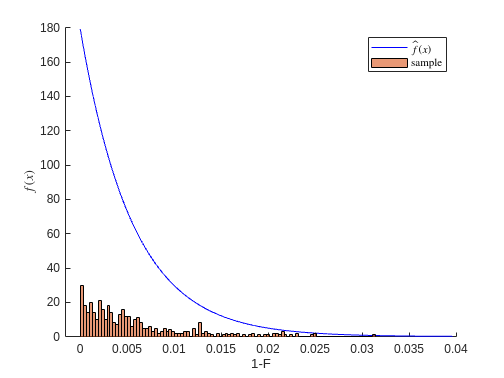

figure('Name','NAP PDF')
hold on;
plot(x_nap, pdf_nap, '-b', DisplayName='$\hat{f}(x)$')
histogram(sample, 100)
xlabel('1-F')
ylabel('$f(x)$','Interpreter','latex')
legend('Interpreter','latex')

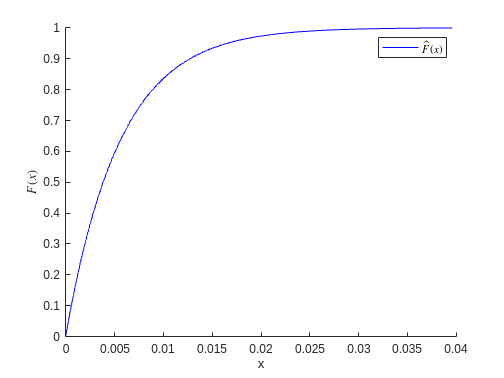


figure('Name','NAP CDF')
hold on;
plot(x_nap, cdf_nap, '-b', DisplayName='$\hat{F}(x)$')
plot(actual.x, actual.cdf_y, '--k', DisplayName='$F(x)$')
xlabel('x')
ylabel('$F(x)$','Interpreter','latex')
legend('Interpreter','latex')

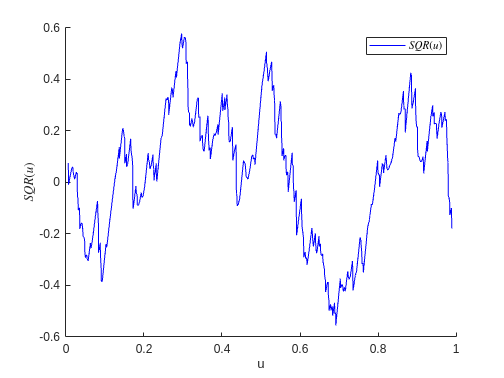

figure('Name','NAP SQR')
hold on;
plot(u_nap, sqr_nap, '-b', DisplayName='$SQR(u)$')
xlabel('u')
ylabel('$SQR(u)$','Interpreter','latex')
legend('Interpreter','latex')


actual.dist_name = "Stable";
actual.Ns = 1e4;

actual = actual.dist_list();
rndom = actual;
rndom.randomVSactual = "random";
rndom = rndom.dist_list();

sample = rndom.rndData;

nse_2 = NAP;
serial = true;
nse_2 = nse_2.stitch(sample, serial);

blocks 17


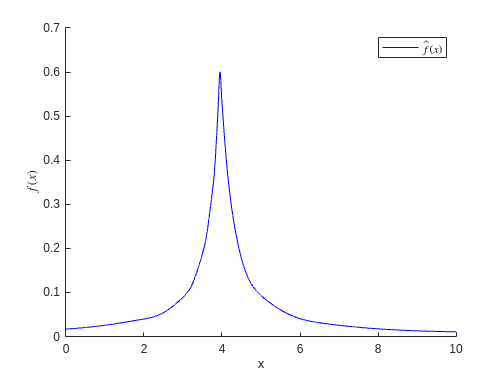

fail_code = nse_2.failed;
x_nap = nse_2.sx;
pdf_nap = nse_2.sPDF;

figure('Name','NAP PDF')
hold on;
plot(x_nap, pdf_nap, '-b', DisplayName='$\hat{f}(x)$')
plot(actual.x, actual.pdf_y, '--k', DisplayName='$f(x)$')
xlim([0,10])
xlabel('x')
ylabel('$f(x)$','Interpreter','latex')
legend('Interpreter','latex')

% Define distribution range if plotting the actual PDF distribution
actual.min_limit = 0;
actual.max_limit = 1;
actual.x = linspace(actual.min_limit,actual.max_limit,1000);

actual.dist_name = "Beta-a0p5-b0p5";
actual.Ns = 2e4;

actual = actual.dist_list();
rndom = actual;
rndom.randomVSactual = "random";
rndom = rndom.dist_list();

sample = rndom.rndData;

nse_2 = NAP;
serial = true;
nse_2 = nse_2.stitch(sample, serial);

blocks 13


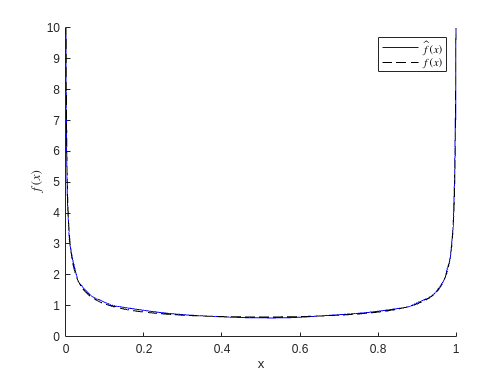

fail_code = nse_2.failed;
x_nap = nse_2.sx;
pdf_nap = nse_2.sPDF;

figure('Name','NAP PDF')
hold on;
plot(x_nap, pdf_nap, '-b', DisplayName='$\hat{f}(x)$')
plot(actual.x, actual.pdf_y, '--k', DisplayName='$f(x)$')
xlim([0,1])
ylim([0,10])
xlabel('x')
ylabel('$f(x)$','Interpreter','latex')
legend('Interpreter','latex')